**Name : Krish Singh**

**Roll: AID25072**

**AID Semester 2**

## **LAB EXCERCISE 8**

1. Consider the function: f(x,y) = 1/(|x| + |y| + 0.5). Plot 15 level curves for the function f(x,y) in the  rectangular domain −5 ≤ x,y ≤ 5. 

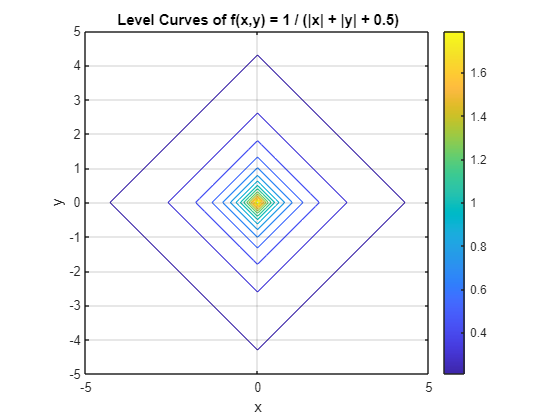

x=linspace(-5,5,400);
y=linspace(-5,5,400);
[X,Y]=meshgrid(x,y);

%Defining function
Z=1./(abs(X)+abs(Y)+0.5);

%plotting 15 level curves
figure;
contour(X,Y,Z,15);
colorbar;%gives 15 level curves

%labels and titles
xlabel('x');
ylabel('y');
title('Level Curves of f(x,y) = 1 / (|x| + |y| + 0.5)');
axis equal;
grid on;

2. Consider the function: f(x,y) = 4x^2 + 9y^2 − 72.

(a) Plot the level curves for f(x,y) with function values written in each curve in  −10 ≤ x,y ≤ 10 

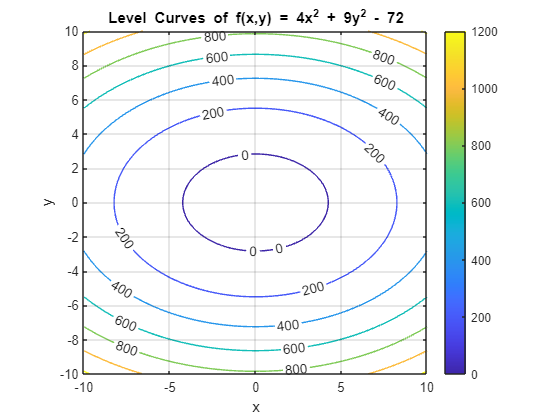

% Domain
x = linspace(-10, 10, 400);
y = linspace(-10, 10, 400);
[X, Y] = meshgrid(x, y);

% Function
Z = 4*X.^2 + 9*Y.^2 - 72;

% Plot level curves with labels
figure;
[C, h] = contour(X, Y, Z); 
clabel(C, h);                 
colorbar;

xlabel('x');
ylabel('y');
title('Level Curves of f(x,y) = 4x^2 + 9y^2 - 72');
axis equal;
grid on;

(b) Find the gradient and hessian of the function using ‘syms’. 

syms x y

f = 4*x^2 + 9*y^2 - 72;

grad_f = gradient(f, [x, y]);

H = hessian(f, [x, y]);

disp('Gradient:');

Gradient:


disp(grad_f);

$$\left(\begin{array}{c} 8\,x\\ 18\,y \end{array}\right)$$

disp('Hessian:');

Hessian:


disp(H);

$$\left(\begin{array}{cc} 8 & 0\\ 0 & 18 \end{array}\right)$$

 (c) Plot the gradient vectors at some points on the level curves. 

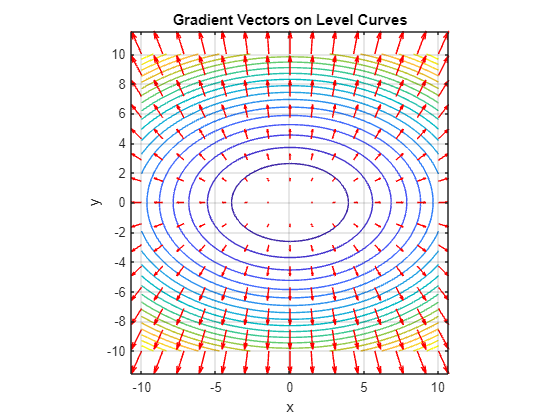

% Grid for vector field (coarser grid for clarity)
xg = linspace(-10, 10, 15);
yg = linspace(-10, 10, 15);
[Xg, Yg] = meshgrid(xg, yg);

% Gradient components
U = 8 * Xg;
V = 18 * Yg;

% Plot contours
figure;
contour(X, Y, Z, 20);
hold on;

% Plot gradient vectors
quiver(Xg, Yg, U, V, 'r');

xlabel('x');
ylabel('y');
title('Gradient Vectors on Level Curves');
axis equal;
grid on;
hold off;

3. Consider the function f(x,y) = sinx + cosy + 3e^(−x2−y2). 

(a) Show the surface plot of the function in one figure and the gradient vectors at some points on level  curves in another figure. 

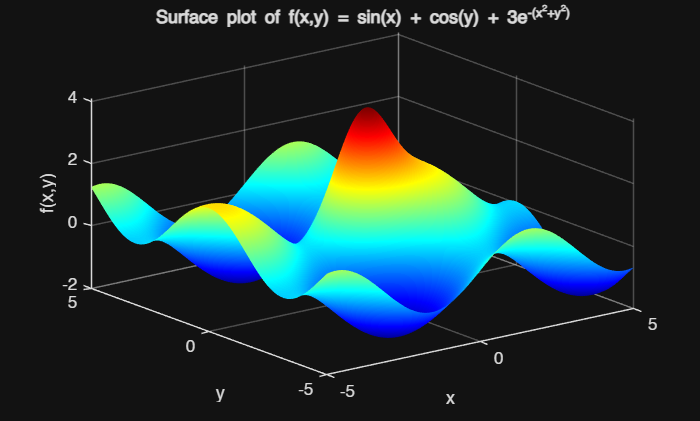

% Domain
x = linspace(-5,5,300);
y = linspace(-5,5,300);
[X,Y] = meshgrid(x,y);

% Function
Z = sin(X) + cos(Y) + 3*exp(-X.^2 - Y.^2);

%% ---- Surface plot ----
figure
surf(X,Y,Z)
shading interp
colormap jet;
xlabel('x'); ylabel('y'); zlabel('f(x,y)')
title('Surface plot of f(x,y) = sin(x) + cos(y) + 3e^{-(x^2+y^2)}')
grid on

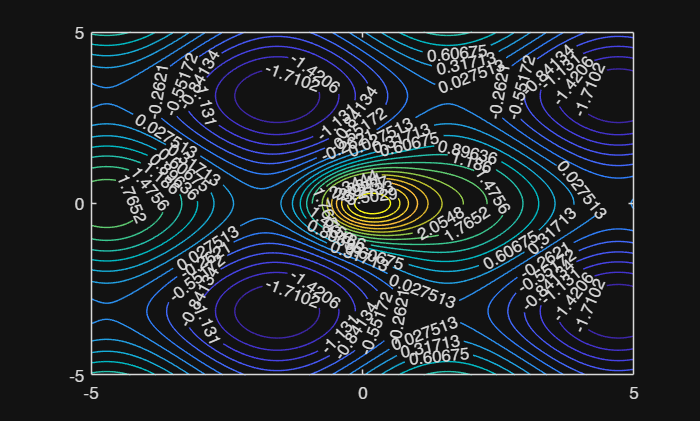


%% ---- Contour + Gradient vectors ----
figure
[C,h] = contour(X,Y,Z,20);
clabel(C,h);

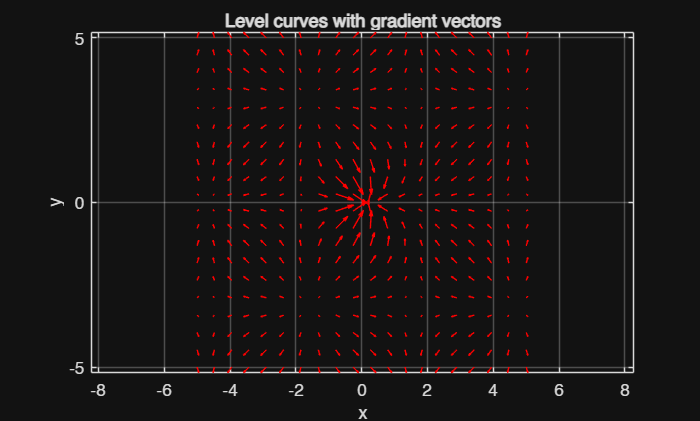


% Coarse grid for vectors
xg = linspace(-5,5,20);
yg = linspace(-5,5,20);
[Xg,Yg] = meshgrid(xg,yg);

% Analytical gradient
U = cos(Xg) - 6*Xg.*exp(-Xg.^2 - Yg.^2);   % df/dx
V = -sin(Yg) - 6*Yg.*exp(-Xg.^2 - Yg.^2); % df/dy

quiver(Xg,Yg,U,V,'r')

xlabel('x'); ylabel('y')
title('Level curves with gradient vectors')
axis equal
grid on

(b) Looking at the surface plot and from the figure with function values on level curves, try to find a  minimum and a maximum for the function.  

% Maximum
[max_val, idx_max] = max(Z(:));
x_max = X(idx_max);
y_max = Y(idx_max);

% Minimum
[min_val, idx_min] = min(Z(:));
x_min = X(idx_min);
y_min = Y(idx_min);

% Display
fprintf('Maximum: f = %.4f at (%.4f, %.4f)\n', max_val, x_max, y_max);

Maximum: f = 4.0821 at (0.1839, -0.0167)


fprintf('Minimum: f = %.4f at (%.4f, %.4f)\n', min_val, x_min, y_min);

Minimum: f = -1.9998 at (4.6990, -3.1271)


4. Consider the function: f(x,y) = x e^{-(x^2 + y^2)

a) Plot the surface given for x and y varying from -2 to 2 

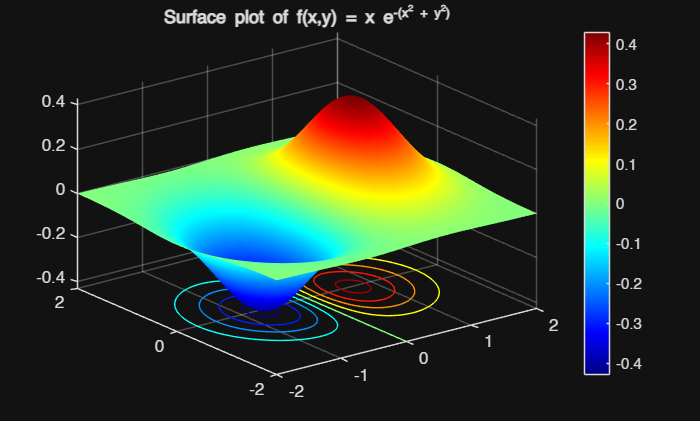

clear;
clc;
close all;
x = linspace(-2,2,200);
y = linspace(-2,2,200);
[X,Y]=meshgrid(x,y);
Z=X.*exp(-(X.^2 + Y.^2));
figure;
surfc(X,Y,Z);
colormap jet;
shading interp;
colorbar;
title('Surface plot of f(x,y) = x e^{-(x^2 + y^2)}')

b) Write the General expression for gradient and Hessian for the function 

syms x y
f = x*exp(-(x^2 + y^2));

grad_f = gradient(f, [x y])

$$grad\_f = \left(\begin{array}{c} {\mathrm{e}}^{-x^{2}-y^{2}}-2\,x^{2}\,{\mathrm{e}}^{-x^{2}-y^{2}}\\ -2\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}} \end{array}\right)$$

hess_f = hessian(f, [x y])

$$hess\_f = \begin{array}{l} \left(\begin{array}{cc} 4\,x^{3}\,\sigma_{1}-6\,x\,\sigma_{1} & 4\,x^{2}\,y\,\sigma_{1}-2\,y\,\sigma_{1}\\ 4\,x^{2}\,y\,\sigma_{1}-2\,y\,\sigma_{1} & 4\,x\,y^{2}\,\sigma_{1}-2\,x\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-x^{2}-y^{2}} \end{array}$$

c) Evaluate Hessian at the points given in the following figures 

H1 = subs(H, [x y], [-0.6 0.2])

$$H1 = \left(\begin{array}{cc} \frac{342\,{\mathrm{e}}^{-\frac{2}{5}}}{125} & -\frac{14\,{\mathrm{e}}^{-\frac{2}{5}}}{125}\\ -\frac{14\,{\mathrm{e}}^{-\frac{2}{5}}}{125} & \frac{138\,{\mathrm{e}}^{-\frac{2}{5}}}{125} \end{array}\right)$$

H2 = subs(H, [x y], [0.6 -0.1])

$$H2 = \left(\begin{array}{cc} -\frac{342\,{\mathrm{e}}^{-\frac{37}{100}}}{125} & \frac{7\,{\mathrm{e}}^{-\frac{37}{100}}}{125}\\ \frac{7\,{\mathrm{e}}^{-\frac{37}{100}}}{125} & -\frac{147\,{\mathrm{e}}^{-\frac{37}{100}}}{125} \end{array}\right)$$

H3 = subs(H, [x y], [1.6 -0.7])

$$H3 = \left(\begin{array}{cc} \frac{848\,{\mathrm{e}}^{-\frac{61}{20}}}{125} & -\frac{721\,{\mathrm{e}}^{-\frac{61}{20}}}{125}\\ -\frac{721\,{\mathrm{e}}^{-\frac{61}{20}}}{125} & -\frac{8\,{\mathrm{e}}^{-\frac{61}{20}}}{125} \end{array}\right)$$

H4 = subs(H, [x y], [-1.4 0.35])

$$H4 = \left(\begin{array}{cc} -\frac{322\,{\mathrm{e}}^{-\frac{833}{400}}}{125} & \frac{511\,{\mathrm{e}}^{-\frac{833}{400}}}{250}\\ \frac{511\,{\mathrm{e}}^{-\frac{833}{400}}}{250} & \frac{1057\,{\mathrm{e}}^{-\frac{833}{400}}}{500} \end{array}\right)$$

H5 = subs(H, [x y], [0 0.2])

$$H5 = \left(\begin{array}{cc} 0 & -\frac{2\,{\mathrm{e}}^{-\frac{1}{25}}}{5}\\ -\frac{2\,{\mathrm{e}}^{-\frac{1}{25}}}{5} & 0 \end{array}\right)$$

d) Find eigenvalues of those Hessian matrices and decide the nature of curvature at the points where it is evaluated. (curved upward, downward, neither) 

eig(H1)

$$ans = \left(\begin{array}{c} -\frac{2\,{\mathrm{e}}^{-\frac{2}{5}}\,\left(\sqrt{106}-24\right)}{25}\\ \frac{2\,{\mathrm{e}}^{-\frac{2}{5}}\,\left(\sqrt{106}+24\right)}{25} \end{array}\right)$$

eig(H2)

$$ans = \left(\begin{array}{c} \frac{{\mathrm{e}}^{-\frac{37}{100}}\,\left(\sqrt{38221}-489\right)}{250}\\ -\frac{{\mathrm{e}}^{-\frac{37}{100}}\,\left(\sqrt{38221}+489\right)}{250} \end{array}\right)$$

eig(H3)

$$ans = \left(\begin{array}{c} -\frac{{\mathrm{e}}^{-\frac{61}{20}}\,\left(\sqrt{28121}-84\right)}{25}\\ \frac{{\mathrm{e}}^{-\frac{61}{20}}\,\left(\sqrt{28121}+84\right)}{25} \end{array}\right)$$

eig(H4)

$$ans = \left(\begin{array}{c} \frac{7\,{\mathrm{e}}^{-\frac{833}{400}}\,\left(\sqrt{197489}-33\right)}{1000}\\ -\frac{7\,{\mathrm{e}}^{-\frac{833}{400}}\,\left(\sqrt{197489}+33\right)}{1000} \end{array}\right)$$

eig(H5)

$$ans = \left(\begin{array}{c} -\frac{2}{5\,\sqrt{{\mathrm{e}}^{2/25}}}\\ \frac{2}{5\,\sqrt{{\mathrm{e}}^{2/25}}} \end{array}\right)$$